# Tarea 1: Coeficientes de la serie de Fourier

### Autores: Maria Fernanda Palacio, Sebastián Suárez y Estefania Laverde

#### Universidad del Rosario

#### Escuela de Ingenieria, Ciencia y Tecnología

## Introducción

El trabajo expuesto se plantea como una solución al problema de envío de una señal, específicamente de la información de un color con el cual los profesionales de Flora y Fauna necesitan trabajar, en una situación con limitantes de ancho de banda. 

Para ello, en base a un color en formato RGB, se encuentran los coeficientes de la Serie de Fourier del color traducido a binario, y posteriormente se reconstruye en base a dichos coeficientes.

A continuación se encuentra el código con el cual fue posible solucionar el problema.

## Procedimiento

El primer paso para encontrar los coeficientes del color, es hayar la función que describe la señal en binario de manera manual. El codigo RGB que se usó es (18, 163, 155), y para trasformarlo a binario simplemente se pasó cada uno de los números a binario y luego se concatenó, obteniendo así la señal 000100101010001110011011. En base en ella se construyó la función expuesta en la línea 19-32.

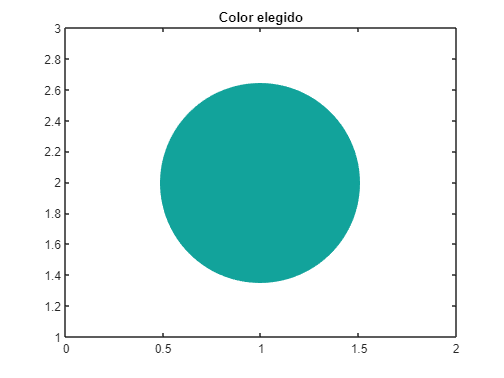


%Inicializacion del codigo
clear all, close all, clc

%Color elegido
plot(1,2,'.','Color','#12a39b','MarkerSize',500)
title('Color elegido')

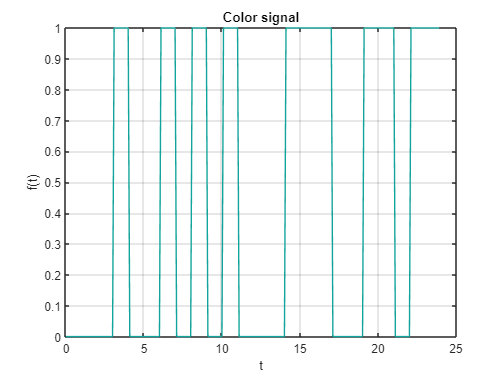


%Variables iniciales

T = 24;          %segundos
Ts = 0.1;        %segundos/muestra
t = 0:Ts:T-Ts;   %vector tiempo de muestreo

%Color en RGB:

% R = 18 = 00010010
% G = 163 = 10100011
% B = 155 = 10011011

%Funcion del color binario

f((t>0)&t<=3)=0;
f((t>3)&(t<=4))=1;
f((t>4)&(t<=6))=0;
f((t>6)&(t<=7))=1;
f((t>7)&(t<=8))=0;
f((t>8)&(t<=9))=1;
f((t>9)&(t<=10))=0;
f((t>10)&(t<=11))=1;
f((t>11)&(t<=14))=0;
f((t>14)&(t<=17))=1;
f((t>17)&(t<=19))=0;
f((t>19)&(t<=21))=1;
f((t>21)&(t<=22))=0;
f((t>22)&(t<=24))=1;

%Grafica de la funcion
plot(t,f,'Color','#12a39b')
grid on
title('Color signal')
xlabel('t'), ylabel('f(t)')

Una vez obtenida la función, se procedió a calcular los coeficientes de la Serie de Fourier, teniendo en cuenta que para un número $N$ de armónicos, los coeficientes están dados por


$$a_n = \frac{2T_s}{T}\sum_t f(t)cos(\frac{2\pi t n}{T})$$



$$b_n = \frac{2T_s}{T}\sum_t f(t)sin(\frac{2\pi t n}{T})$$


Teniendo en cuenta que $T$ es el periodo de la señal, $T_s$ son los segundos de muestreo,  y que se convierte en una sumatoria en vez de una integral por el hecho de que la función ya está evaluada en unos valores del tiempo. Note que estos coeficientes separan la integral original en la parte real e imaginaria para trabajarla más comodamente.

Luego de contar con los coeficientes, se visualizan en la gráfica expuesta enseguida.

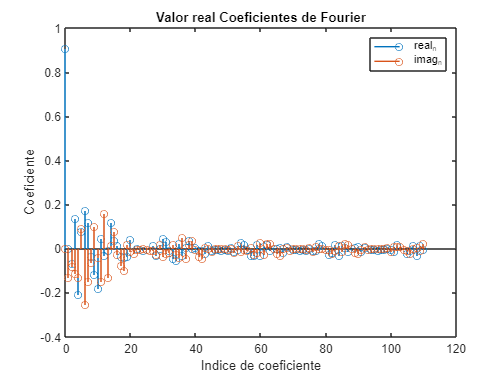


%Calculo de coeficientes de Fourier
N = 110; 
realc = zeros(1,N+1);
imagc = zeros(1,N+1);

for n=0:N
    cosTerm = cos(2*pi*t*n/T);
    sinTerm = sin(2*pi*t*n/T);
    
    realc(n+1) = (2*Ts/T)*sum(f.*cosTerm);
    imagc(n+1) = (2*Ts/T)*sum(f.*sinTerm);
end

%Visualizar coeficientes 

stem(0:N, realc)
hold on
stem(0:N, imagc)
hold off
xlabel('Indice de coeficiente')
ylabel('Coeficiente')
legend('real_n','imag_n')
title('Valor real Coeficientes de Fourier')

Contando con los coeficientes, se procede a reconstruir la señal del color, lo cual se hace de manera sencilla teniendo en cuenta que la representación de la Serie de Fourier con los coeficientes obtenidos es 


$$f_r(t) = \frac{a_0}{2}+\sum_{n=0}^{N}(a_ncos(\frac{2\pi nt}{T})+b_nsin(\frac{2\pi nt}{T}))$$


Y luego, se grafica la reconstrucción.

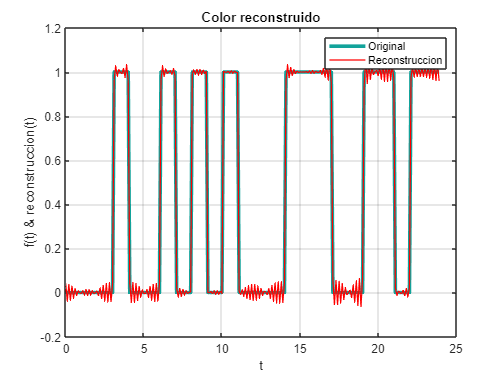

%Reconstruccion de la señal
f_reconstruida = (realc(1)/2)*ones(size(t));

for n=1:N
   cosTerm = cos(2*pi*t*n/T);
   sinTerm = sin(2*pi*t*n/T); 

   f_reconstruida = f_reconstruida + realc(n+1)*cosTerm + imagc(n+1)*sinTerm; 
end

plot(t,f,'Color','#12a39b',"LineWidth",3)
hold on
plot(t,f_reconstruida,"LineWidth",1,'Color','r')
hold off
grid on
title('Color reconstruido');
xlabel('t');
ylabel('f(t) & reconstruccion(t)')
legend('Original','Reconstruccion')

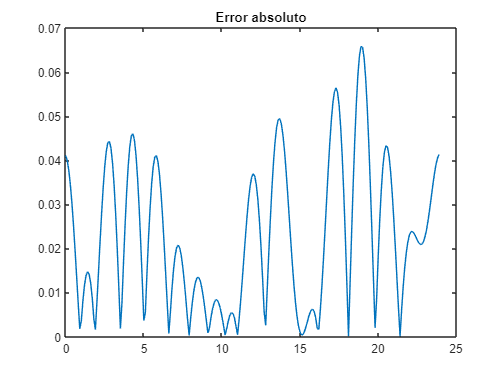

%Calculo del error
errorN = abs(f_reconstruida-f);
plot(t,errorN)
title('Error absoluto');

%Error cuadrático medio
ErrorC = mean((f_reconstruida-f).^2)

ErrorC = 7.9215e-04

tm = size(f_reconstruida);
RMSE = sqrt(sum(f_reconstruida-f).^2)./tm

RMSE = 	1.0e+-13 *

    0.5726    0.0024


Para la segunda parte del trabajo, se cuenta con los coeficientes de la señal del grupo conformado por Alejandra Campo, Alejandro Garcia y 

Javier Lizarazo y se requiere reconstruir la señal. Para ello, se hace uso del mismo código expuesto anteriormente y a continuación se muestran los resultados.

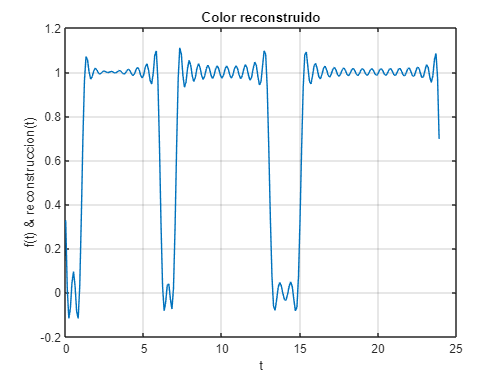


%Parte dos: reconstrucción del color de otro grupo.

%Coeficientes recibidos, separados en parte real e imaginaria

realc2 = [1.65833333333333	0.0629604820375175	-0.0842841843530350	-0.122000527933764	-0.0667697879360665 ...
    -0.125888783887524	0.0975517061347891	-0.179834946038350	-0.0364153388259183	0.0428224352690319	...
    -0.0277662602506121	-0.0511920240116127	0.00833333333333319	0.0429345724199022	-0.000701111735936573 ...
    -0.0133288015307497	0.0148930382925733	0.0686854870461942	-0.0430441647507528	0.0258904068843070	...
    0.0155502116982036	-0.00117789409244385	0.00230832131283360	-0.0111910479317688	-0.00833333333333245...
    -0.00544745742692165	-0.0106080459959000	-0.0272460238920050	-0.00731697212144128	-0.0250651494387624...
    0.0117851130197753	-0.0408895989604220	-0.0101880204334782	0.0166566450420859	-0.0163095716805348...
    -0.0151515537097792	0.00833333333333308	0.0139267311016530	-0.00810474983653206	0.000178327666633238	0.00416666666666676];

imagc2 = [0	-0.00991409825981216	-0.139884066177551	0.189735741174115	-0.202370279679604	-0.0550250567420664...
    0.00833333333333289	-0.0733225260594960	-0.0630732170213267	-0.130609239398318	0.0253254834271674	...
    -0.0638967147473237	-0.105229191911251	-0.0402689885435503	0.0215527289146486	-0.0843616786540094	-0.0257954990018051...
    -0.00693917588734573	-0.00833333333333314	-0.00425262296618924	-0.0352670900630735	0.0311796398246321	...
    -0.0100985531904292	-0.00138866515686392	7.95659834314696e-17	0.000513181607632237	-0.0122732512375194...
    0.0164840357922911	-0.0307447836063293	-0.0156481758963861	0.00833333333333346	-0.0284489923397330	-0.0176461690193364	...
    -0.0304354183530552	0.00548191673729921	-0.0240123347925493	-0.0327101750917522	-0.00816730521046686	0.00872925156356209	...
    -0.0326506188572990	-0.00721687836487008];

N2 = length(imagc2)-1;

%Reconstruccion de la señal
w_reconstruida = (realc2(1)/2)*ones(size(t));

for n=1:N2
   cosTerm2 = cos(2*pi*t*n/T);
   sinTerm2 = sin(2*pi*t*n/T); 
   w_reconstruida = w_reconstruida + realc2(n+1)*cosTerm2 + imagc2(n+1)*sinTerm2; 
end

plot(t,w_reconstruida)
hold off
grid on
title('Color reconstruido');
xlabel('t');
ylabel('f(t) & reconstruccion(t)')

Con la grafica de la señal es sencillo observar que el código binario del color es 0011111011111100111111111

% codigo de color en RGB
red=bin2dec('001111101');
green=bin2dec('11111001');
blue=bin2dec('11111111');
rgb=[red green blue];
disp(rgb)

   125   249   255



El codigo RGB resultante es (126,254,127), el color se muestra en el siguiente grafico.

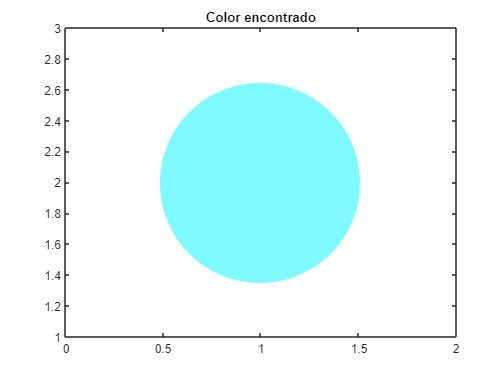

plot(1,2,'.','Color','#7DF9FF','MarkerSize',500)
title('Color encontrado')